# PROYECTO PRIME

Teresa González García y María José Medina Hernández

format compact; clear all; close all;

## Implementación de todos los modos de comunicación de PRIME en el caso de canal sin distorsión y sin FEC 

### 1. Elección de los parámetros de simulación

#### Parámetros generales

Fs=250*10^3; % Frecuencia de muestreo
Ts=1/Fs; % Periodo de muestreo

#### Parámetros de modulación PSK

m_ary=[2 4 8]; % Número de símbolos de la constelación PSK
m_dpsk=log2(m_ary);

#### Parámetros de modulación OFDM

Estos parámetros han sido sacados del estándar, centrándonos únicamente en el payload.

Nc= 96; % Número de portadoras
NFFT=512; % Tamaño FFT
Ncp=48; % Tamaño prefijo ciclico
Tsimb=2.24*10^-3; % NFFT*Ts + Ncp*Ts. Duracion total simbolo OFDM
delta_f=Fs/NFFT; % Separacion entre f portadoras

#### Parámetros de corrección de errores

R=1/2; %Convolutional coding rate

#### Parámetros de aleatorización y desfase

% Secuencia PRBS
scrambler = [0,0,0,0,1,1,1,0,1,1,1,1,0,0,1,0,1,1,0,0,1,0,0,1,0,0,0,0,0,0,1,0,0,0,1,0,0,1,1,0,0,0,1,0,1,1,1,0,1,0,1,1,0,1,1,0,0,0,0,0,1,1,0,0,1,1,0,1,0,1,0,0,1,1,1,0,0,1,1,1,1,0,1,1,0,1,0,0,0,0,1,0,1,0,1,0,1,1,1,1,1,0,1,0,0,1,0,1,0,0,0,1,1,0,1,1,1,0,0,0,1,1,1,1,1,1,1];

#### Parámetros de simulación

Para calcular el número de símbolos OFDM por trama, tenemos en cuenta que, como máximo, esta puede durar 100ms ya que es el tiempo máximo en el que se puede considerar el canal estable cuando sea dispersivo. Obtenemos Nofdm = 44.

Tmax=100*10^-3; % Duración máxima de una trama
Nofdm= floor(Tmax/(Tsimb)); % Nofdm

Puesto que se quieren obtener valores de BER fiables inferiores incluso a 10^-4, se necesitan transmitir al menos 10^-4 bits si se quiere obtener esta sensibilidad. Para sencillez del código, se utilizará un número de bits proporcional al número de portadoras, a log2(m-ary) y al número de símbolos OFDM por trama. El mínimo común múltiplo de estos cuatro parámetros es mayor a 10^-4, por lo que es un tamaño válido. En total obtenemos 25344.

Nbits = Nc*lcm(2,3)*Nofdm;

A continuación, obtenemos el número de bits por trama y el número de tramas para modulación. 

Para calcular el número de bits por trama en cada modulación, se multiplica el número de símbolos/trama* bits/símbolo (número de portadoras*log2(m_ary). Se obtienen 4224 para DBPSK, 8448 para  DQPSK y12672 para D8PSK.

Para calcular el número total de tramas, se divide el número total de bits entre los bits por trama. En total obtenemos 6 para DBPSK, 3 para DQPSK y 2 para DBPSK.

Nbits_trama_DPSK= Nofdm*Nc*m_dpsk;
N_tramas_DPSK=Nbits./Nbits_trama_DPSK;

### 2. Comportamiento del sistema en un canal ideal

#### Transmisión con aleatorización 

% TODO: poner un flag para que aleatorice o no para demostrar que funciona sin y con aleatorización

% Generación de una secuencia de bits aleatoria
txbits = randi(2,1,Nbits)-1;

% Transmisión con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
x_tx_DBPSK= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT);
x_tx_DQPSK= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT);
x_tx_D8PSK= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT);

% Recepción con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
rxbits_DBPSK=receptor(x_tx_DBPSK, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
rxbits_DQPSK=receptor(x_tx_DQPSK, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
rxbits_D8PSK=receptor(x_tx_D8PSK, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);

#### Cálculo del error de transmisión

Cálculo del error de transmisión mediante la comparación de los bits transmitidos con los recibidos

error_dbpsk = sum(abs(txbits-rxbits_DBPSK))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-rxbits_DQPSK))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-rxbits_D8PSK))

error_d8psk = 0

Como se puede observar, el error de transmisión-recepción, incluyendo aleatorización es 0. Esto es lo esperable, ya que se está simulando el sistema en un canal ideal (h[n]=1) y sin ruido.

#### Transmisión en presencia de ruido AWGN

A continuación se van a comparar las gráficas de BER vs SNR teóricas y reales para cada tipo de modulación.

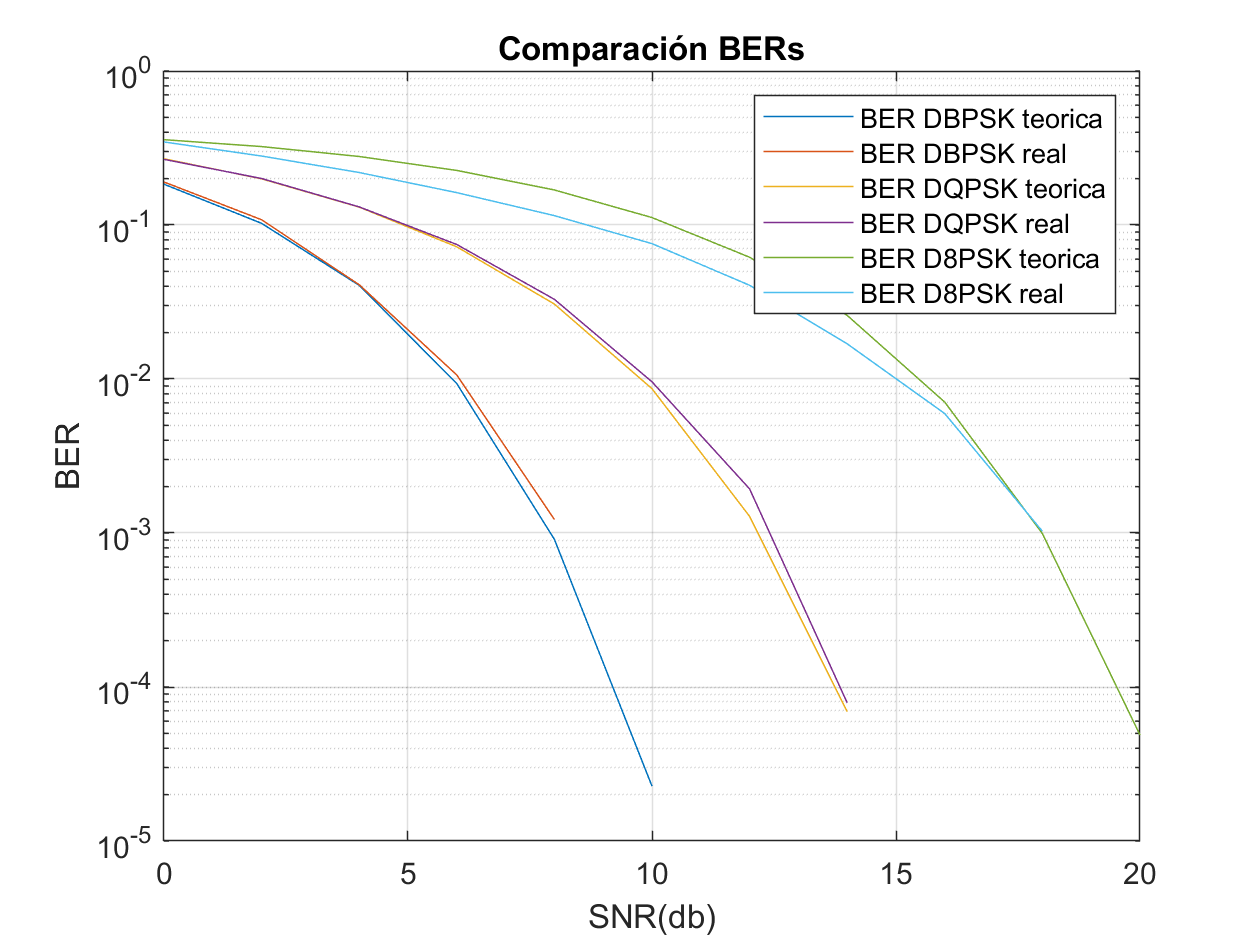

% vector SNR
SNR_db = 0:2:35;

% Cálculo del factor de ancho de banda para distribuir SNR tan solo en la parte
% del espectro con portadoras (Nc)
fb = 10*log10( (NFFT/2)/Nc);

%BER's teoricas de cada modulacion
BER_teor_DBPSK= DBPSK_BER(SNR_db);
BER_teor_DBPSK(find(BER_teor_DBPSK<1e-6))=NaN;
BER_teor_DQPSK= DQPSK_BER(SNR_db);
BER_teor_DQPSK(find(BER_teor_DQPSK<1e-6))=NaN;
BER_teor_D8PSK= D8PSK_BER(SNR_db);
BER_teor_D8PSK(find(BER_teor_D8PSK<1e-6))=NaN;

% Bucle calculo BER_real_DBPSK
for k=1:length(SNR_db)
    
    % Se añade AWGN a la señal de entrada, ajustando la SNR con el factor de ancho de banda.
    y_noise_dbpsk=awgn(x_tx_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_dqpsk=awgn(x_tx_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_d8psk=awgn(x_tx_D8PSK,SNR_db(k)-fb,'measured');
    
    % Se calcula la salida del receptor en presencia de AWGN para cada
    % modulación.
    y_rx_noise_dbpsk=receptor(y_noise_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_dqpsk=receptor(y_noise_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_d8psk=receptor(y_noise_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    % Se calcula la diferencia entre los bits de información transmitidos y
    % los bits a la salida del receptor.
    diferencia_dbpsk=abs(txbits-y_rx_noise_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_d8psk);
    
    % Se calcula las BERs reales como el número total de bits diferentes
    % entre el número de bits transmitidos.
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

% Representacion BER vs SNR para todos los tipos de modulacion
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

Como se esperaba, la BER real es ligeramente mayor que la teórica en todos los casos. Esta mínima diferencia se debe a la presencia de AWGN, pero se hará mayor cuando se incluya un canal no ideal. 

Para una SNR=5db, se puede ver que la BER real es prácticamente idéntica a la teórica en los casos tanto de DBPSK como DQPSK. Sin embargo, en el caso de D8PSK la diferencia es de 0.2.

Para una BER de $10^{-3}$, se necesita la siguiente SNR:

- DBPSK -> SNR= 8 db

- DQPSK -> SNR= 12 db

- D8PSK -> SNR= 18 db

Por tanto se demuestra que a mayor número de puntos de la constelación (en este caso D8PSK), se necesita una mayor SNR para obtener el mismo nivel de BER, y también la BER real difiere más que la teórica, ya que dichos puntos se encuentran más juntos.

        2.   Inclusión de modelo de canal e inclusión de ecualizador

%canal variante en f. Corresponde a un filtro digital de k=9 posiciones en total (en el dominio del tiempo
% discreto):
h=[-0.1,0.3,-0.5,0.7,-0.9,0.7, -0.5, 0.3, -0.1]; % h=[a0...a8]; atenuaciones

   h[n] produce atenuación y retardo por reflexiones dentro de un canal multipath (retardo máximo 8) en la señal a transmitir.

s(t) -> TX

y(t)-> RX

y(t)=conv(s(t),h(t)) -> dominio discreto -> y[n]= conv(s[n],h[n]). 

y[n]=sum(att*s[n-k])- Seguir con esto en latex

 y = x[n]*h[n] = -0.1·x[n]+0.3·x[n-1]-0.5·x[n-2]+0.5·x[n-3]-0.9·x[n-4]+0.7·x[n-5]-0.5·x[n-6]+0.3·x[n-7]-0.1·x[n-8]

H(f) en dbW

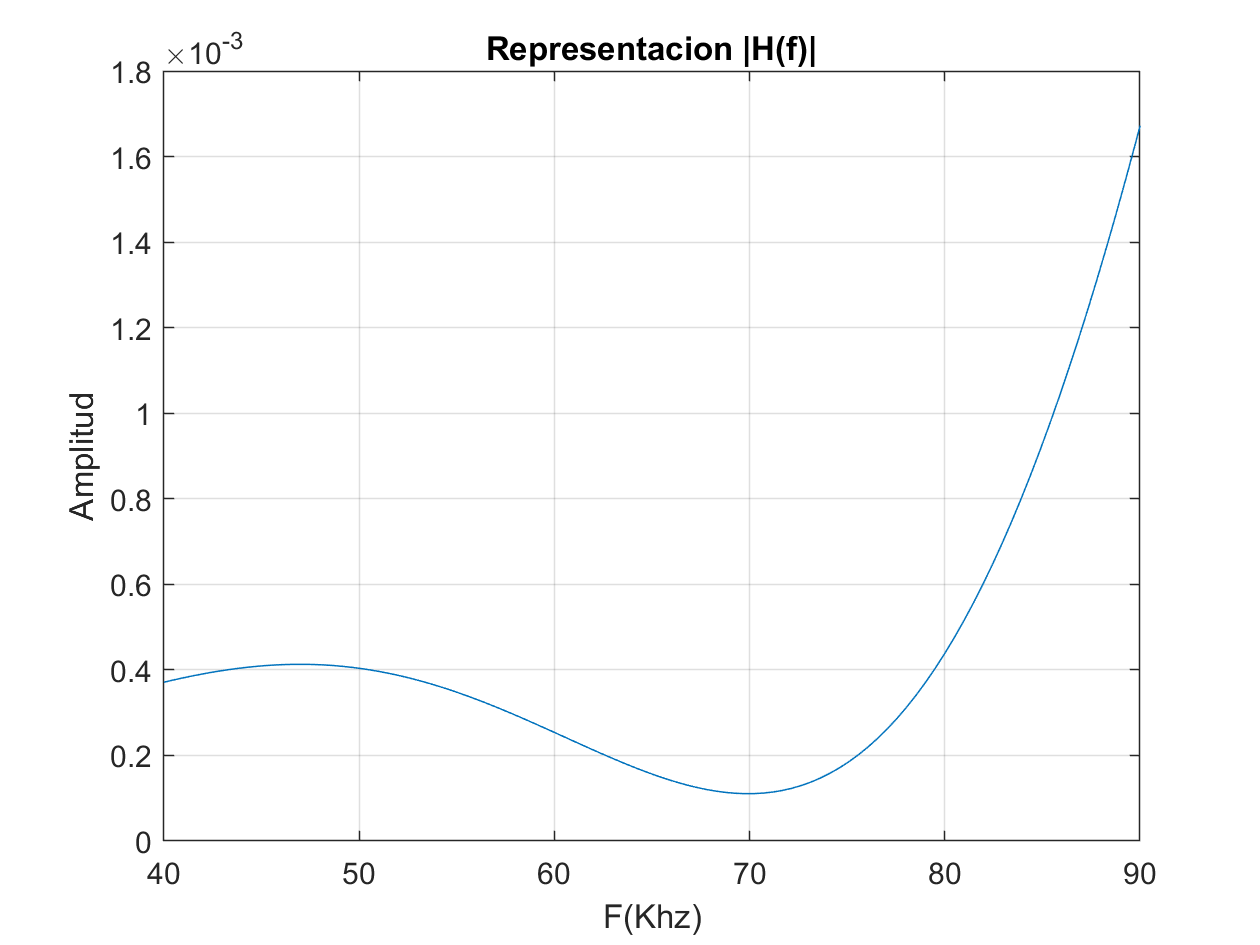

% vector f (paso Fs) -> mitad puntos NFFT espectro + y mitad -. Preguntar

% H(f) es la respuesta al impulso del canal -> FFT.
H=fft(h,NFFT)/NFFT;
f=linspace(-Fs/2,Fs/2, length(H));

%Representacion |H(f)| en el dominio de la frecuencia (unidades naturales)
figure
plot(f/1000,abs(fftshift(H)));
title('Representacion |H(f)|');
xlabel('F(Khz)');
xlim([40,90]);
ylabel('Amplitud');
grid on

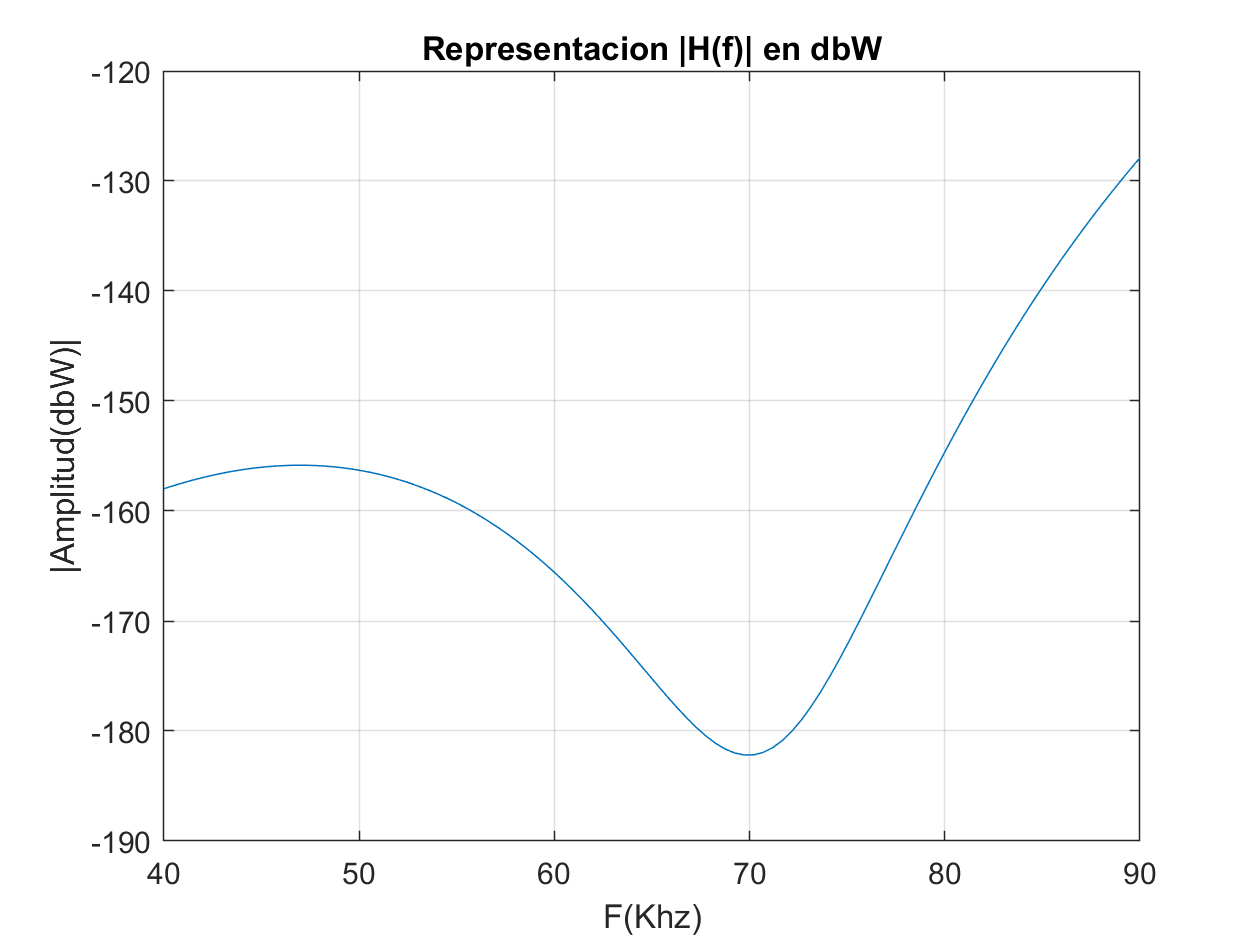

% Representacion |H(f)| el dominio de la frecuencia (db)
figure
plot (f/1000,20*log(abs(fftshift(H))))
title('Representacion |H(f)| en dbW');
xlabel('F(Khz)');
ylabel('|Amplitud(dbW)|');
grid on
xlim([40,90]);

## Con canal

Variables globales

global pilotos_dbpsk
global pilotos_dqpsk
global pilotos_d8psk

%convolucion lineal sin cp y añadimos awgn
y_canal_DBPSK=conv(x_tx_DBPSK,h);
y_canal_DBPSK =y_canal_DBPSK(1:end-length(h)+1)

y_canal_DBPSK =     0.6000   -1.8702    2.3641   -1.9662    2.8534   -2.4568    0.0775    0.0778    1.1954    1.1702   -1.6465   -2.0087    1.0352    1.2244    0.7094    0.9765   -2.2728   -3.2686    2.3078    4.2967   -1.1230   -3.1553    0.0821   -0.0528    0.4829    3.2014   -1.3660   -2.8409    2.2119   -2.0950   -1.0234    7.4532   -2.5122   -7.2017    4.6566    0.8565   -1.4481    4.4958   -4.9884   -2.1254    7.1914   -5.3617   -1.5451    8.3714   -5.5996   -2.4201    4.6939   -5.5804    4.4509    6.0468


y_canal_DQPSK=conv(x_tx_DQPSK,h);
y_canal_DQPSK =y_canal_DQPSK(1:end-length(h)+1)

y_canal_DQPSK =     1.0000   -3.2305    5.0742   -5.6141    5.7708   -2.4486   -1.8872    3.7618   -2.2377    0.8957    0.4321   -2.8542    2.6906    0.5818   -2.7075    2.2959   -0.5315   -0.7961    2.1940   -4.1507    0.5451    6.6408   -3.7241   -3.8806    1.6788   -0.1152    4.5345    0.5492   -7.5640    1.2398    3.2652   -0.1985    3.5738   -4.1713   -5.3787    6.0729    1.5321   -1.3672    1.5154   -5.8584    0.4498    7.7800   -3.7376   -2.7226    2.2525   -2.8166    3.8732    2.5465   -8.2762    2.1091



y_canal_D8PSK=conv(x_tx_D8PSK,h);
y_canal_D8PSK =y_canal_D8PSK(1:end-length(h)+1)

y_canal_D8PSK =     1.0142   -2.1811    0.5317    2.4463   -2.4209    4.4037   -4.6344   -2.1784    6.5276   -0.6307   -3.0154    0.7902   -3.1690    2.7173    5.8313   -5.0256   -3.3254    2.0944   -0.1173    3.6375    0.4279   -5.8479    1.1922    2.2183   -0.8002    2.6451   -2.1082   -3.1819    3.6965   -0.1494   -1.4129    2.0639   -2.0079    0.1186    2.0665   -3.0229    1.2949    2.2034   -3.5656    1.5833    1.8727   -3.4205    1.1336    0.9026   -1.0993    2.7479   -1.8901   -3.0242    3.3608   -0.2606


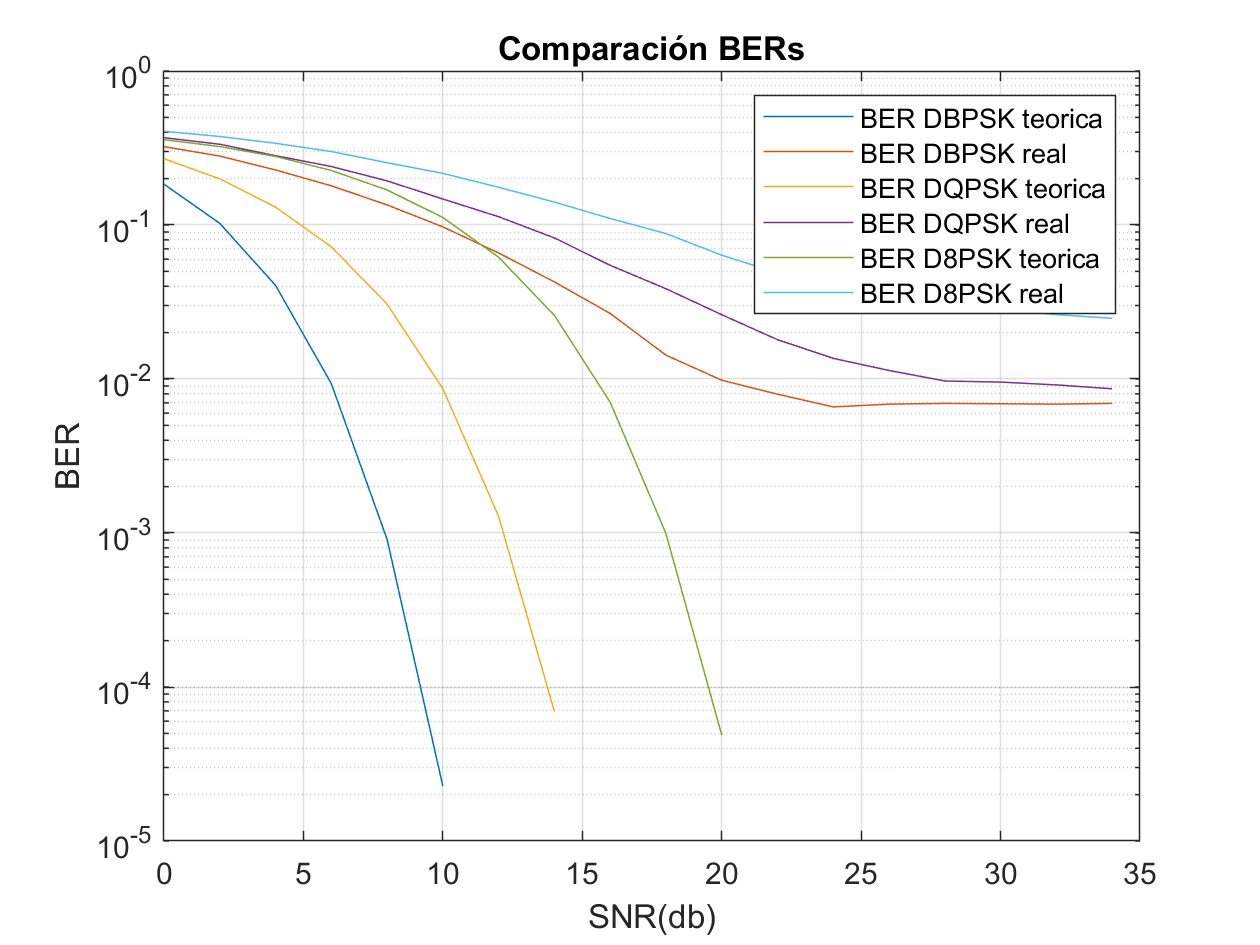

%añadimos el ruido
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_dqpsk=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_d8psk=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

FONDO DE BER EN TORNO 10^-2. eq lo quitara. BPSK MENOR BER

%incluir prefijo ciclico ncp=48. asi se puede recuperar el canal con la
%inversa (problema FFT)
%vectores extendidos
x_tx_DBPSK_cp= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_DQPSK_cp= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_D8PSK_cp= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT, Ncp);

Suponemos que desconocemos el canal.  Finjimos que conocemos el primer simbolo OFDM que recibes entre el primero que has enviado para estimar el canal

%receptor sin ruido para ver que nos quita bien el prefijo

y_rx_DBPSK_cp=receptor(x_tx_DBPSK_cp, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_DQPSK_cp=receptor(x_tx_DQPSK_cp, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_D8PSK_cp=receptor(x_tx_D8PSK_cp, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);


Comprobacion tras ecualizacion y sin ruido error=0.

error_dbpsk = sum(abs(txbits-y_rx_DBPSK_cp))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-y_rx_DQPSK_cp))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-y_rx_D8PSK_cp))

error_d8psk = 0

Convolucionamos con la extendida

y_canal_DBPSK_cp=conv(x_tx_DBPSK_cp,h);
y_canal_DBPSK_cp =y_canal_DBPSK_cp(1:end-length(h)+1);

y_canal_DQPSK_cp=conv(x_tx_DQPSK_cp,h);
y_canal_DQPSK_cp =y_canal_DQPSK_cp(1:end-length(h)+1);

y_canal_D8PSK_cp=conv(x_tx_D8PSK_cp,h);
y_canal_D8PSK_cp =y_canal_D8PSK_cp(1:end-length(h)+1);

Añadimos ruido para calcular BER

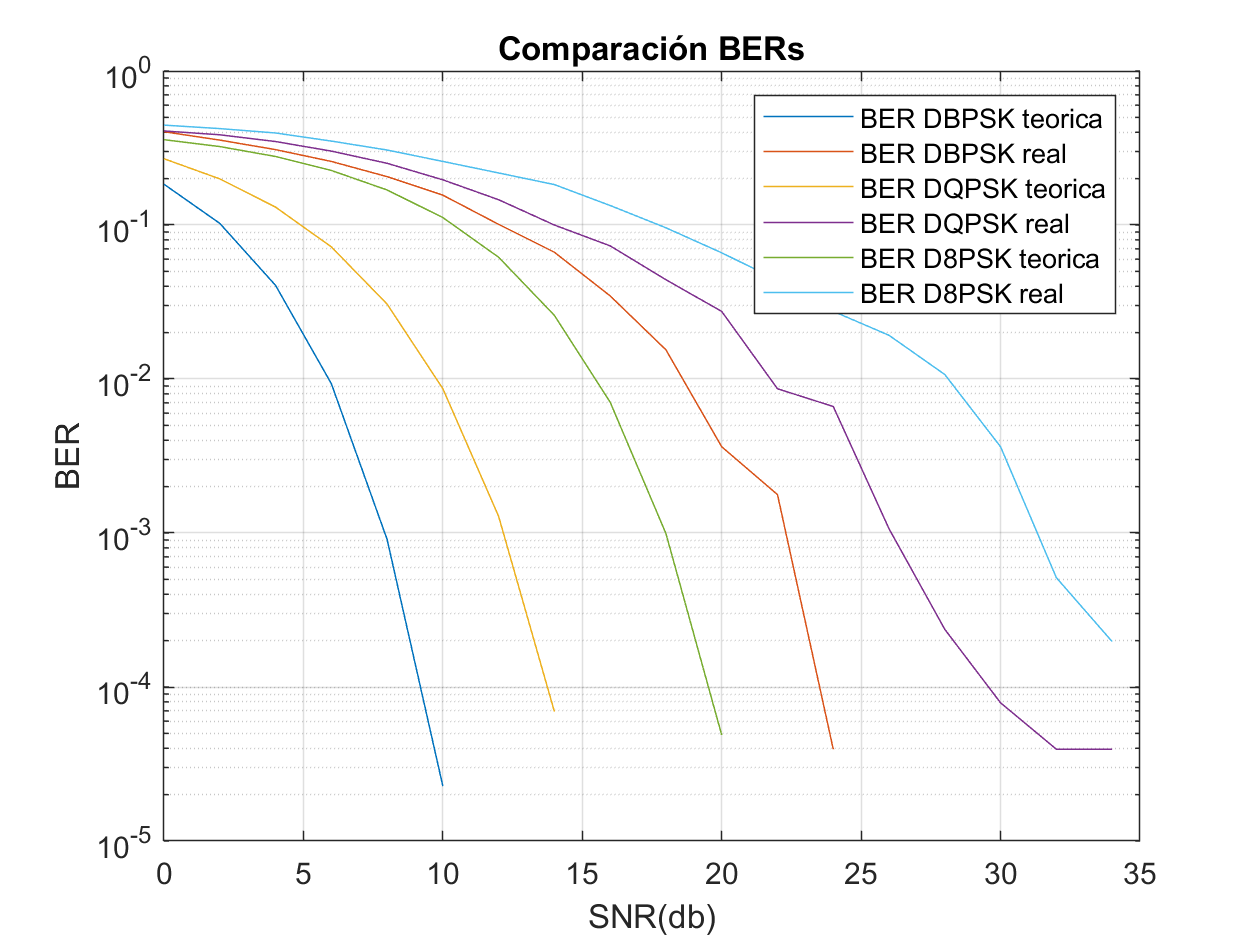

%añadimos el ruido

for k=1:length(SNR_db)
  
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK_cp,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk_cp=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_dqpsk_cp=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_d8psk_cp=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk_cp);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk_cp);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk_cp);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

## FEC

4. Parametros

Debido a la redundancia del FEC (R=1/2), los bits de información en una trama se reducen a la mitad. El número de bits por trama se mantiene fijo por el estándar (payload).

Ya que el numero de bits de informacion es la mitad, el numero de tramas necesario para transmitir todos los bits será el doble.

 Además, se añade zero-padding de tamaño 8 (Nflush) para inicializar los registros del código convolucional.


Ntramas = [12, 6, 4];
Nflush=8;

%3 Nbits en funcion de Ntrama. 
Nbits_1 = Ntramas(1)*((Nbits_trama_DPSK(1)*R)-Nflush);
Nbits_2 = Ntramas(2)*((Nbits_trama_DPSK(2)*R)-Nflush);
Nbits_3 = Ntramas(3)*((Nbits_trama_DPSK(3)*R)-Nflush);
txbits_1 = randi(2,1,Nbits_1)-1;
txbits_2 = randi(2,1,Nbits_2)-1;
txbits_3 = randi(2,1,Nbits_3)-1;


   5. Modulos Interleaving y FEC integrados sin ruido

%con prefijo
x_tx_DBPSK_cp_FEC= transmisor(txbits_1', m_ary(1), Nbits_trama_DPSK(1), Ntramas(1), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_DQPSK_cp_FEC= transmisor(txbits_2', m_ary(2), Nbits_trama_DPSK(2), Ntramas(2), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_D8PSK_cp_FEC= transmisor(txbits_3', m_ary(3), Nbits_trama_DPSK(3), Ntramas(3), Nc,scrambler, Nofdm, NFFT, Ncp, R);


y_rx_DBPSK_cp_FEC=receptor(x_tx_DBPSK_cp_FEC, m_ary(1), Nbits_trama_DPSK(1), Ntramas(1), Nc, scrambler, Nofdm, NFFT, Ncp, R);
y_rx_DQPSK_cp_FEC=receptor(x_tx_DQPSK_cp_FEC, m_ary(2), Nbits_trama_DPSK(2), Ntramas(2), Nc, scrambler, Nofdm, NFFT, Ncp, R);
y_rx_D8PSK_cp_FEC=receptor(x_tx_D8PSK_cp_FEC, m_ary(3), Nbits_trama_DPSK(3), Ntramas(3), Nc, scrambler, Nofdm, NFFT, Ncp, R);


Comprobar error tras FEC

error_dbpsk = find(txbits_1-y_rx_DBPSK_cp_FEC)

error_dbpsk =
  1×0 empty double row vector


error_dqpsk = find(txbits_2-y_rx_DQPSK_cp_FEC)

error_dqpsk =
  1×0 empty double row vector


error_d8psk = find(txbits_3-y_rx_D8PSK_cp_FEC)

error_d8psk =
  1×0 empty double row vector


BER con FEC y sin FEC para todas las modulaciones incluyendo el canal

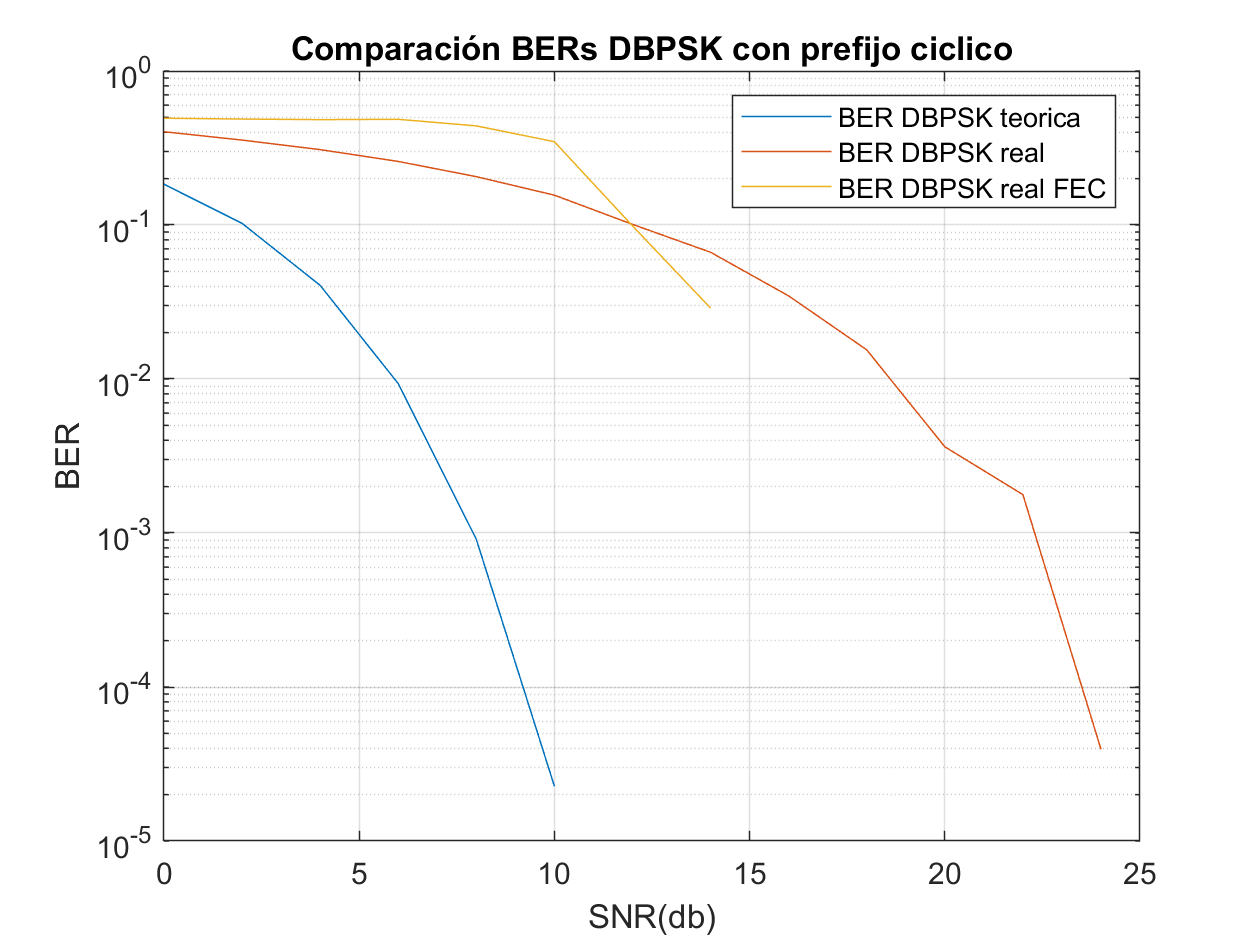

y_canal_DBPSK_cp_FEC=conv(x_tx_DBPSK_cp_FEC,h);
y_canal_DBPSK_cp_FEC =y_canal_DBPSK_cp_FEC(1:end-length(h)+1);

y_canal_DQPSK_cp_FEC=conv(x_tx_DQPSK_cp_FEC,h);
y_canal_DQPSK_cp_FEC =y_canal_DQPSK_cp_FEC(1:end-length(h)+1);

y_canal_D8PSK_cp_FEC=conv(x_tx_D8PSK_cp_FEC,h);
y_canal_D8PSK_cp_FEC =y_canal_D8PSK_cp_FEC(1:end-length(h)+1);
 
for k=1:length(SNR_db)
  
    y_noise_canal_dbpsk_FEC=awgn(y_canal_DBPSK_cp_FEC,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk_FEC=awgn(y_canal_DQPSK_cp_FEC,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk_FEC=awgn(y_canal_D8PSK_cp_FEC,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk_cp_FEC=receptor(y_noise_canal_dbpsk_FEC, m_ary(1), Nbits_trama_DPSK(1), Ntramas(1), Nc, scrambler, Nofdm, NFFT, Ncp, R);
    y_rx_noise_canal_dqpsk_cp_FEC=receptor(y_noise_canal_dqpsk_FEC, m_ary(2), Nbits_trama_DPSK(2), Ntramas(2), Nc, scrambler, Nofdm, NFFT, Ncp, R);
    y_rx_noise_canal_d8psk_cp_FEC=receptor(y_noise_canal_d8psk_FEC, m_ary(3), Nbits_trama_DPSK(3), Ntramas(3), Nc, scrambler, Nofdm, NFFT, Ncp, R);
    
 
    diferencia_dbpsk=abs(txbits_1-y_rx_noise_canal_dbpsk_cp_FEC);
    diferencia_dqpsk=abs(txbits_2-y_rx_noise_canal_dqpsk_cp_FEC);
    diferencia_d8psk=abs(txbits_3-y_rx_noise_canal_d8psk_cp_FEC);
    
    BER_real_DBPSK_FEC(k)= (sum(diferencia_dbpsk)/length(txbits_1));
    BER_real_DBPSK_FEC(find(BER_real_DBPSK_FEC<1e-6))=NaN;
    
    BER_real_DQPSK_FEC(k)= (sum(diferencia_dqpsk)/length(txbits_2));
    BER_real_DQPSK_FEC(find(BER_real_DQPSK_FEC<1e-6))=NaN;
    
    BER_real_D8PSK_FEC(k)= (sum(diferencia_d8psk)/length(txbits_3));
    BER_real_D8PSK_FEC(find(BER_real_D8PSK_FEC<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK_FEC)
title('Comparación BERs DBPSK con prefijo ciclico')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DBPSK real FEC')
grid on

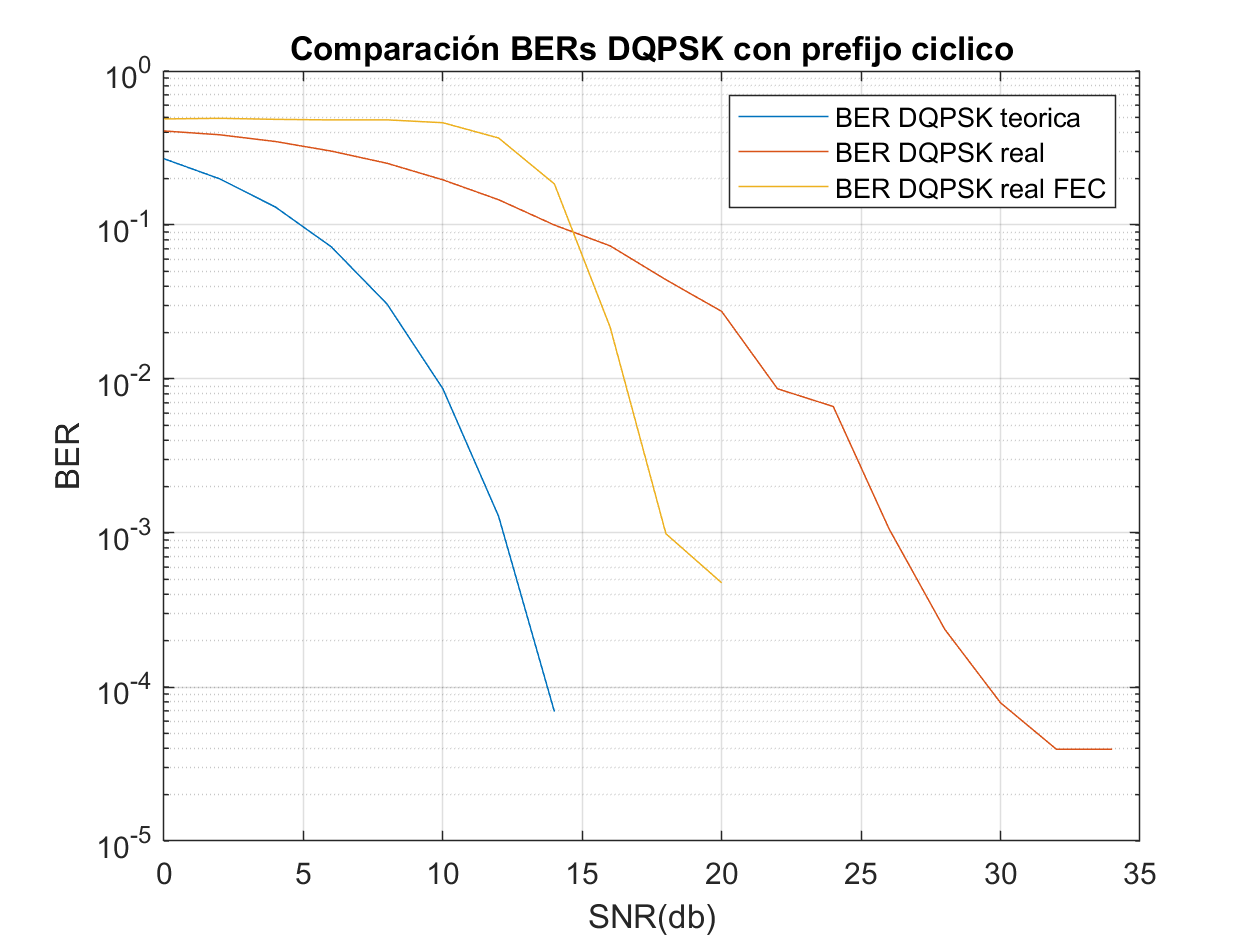



figure
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK_FEC)
title('Comparación BERs DQPSK con prefijo ciclico')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DQPSK teorica', 'BER DQPSK real', 'BER DQPSK real FEC')
grid on

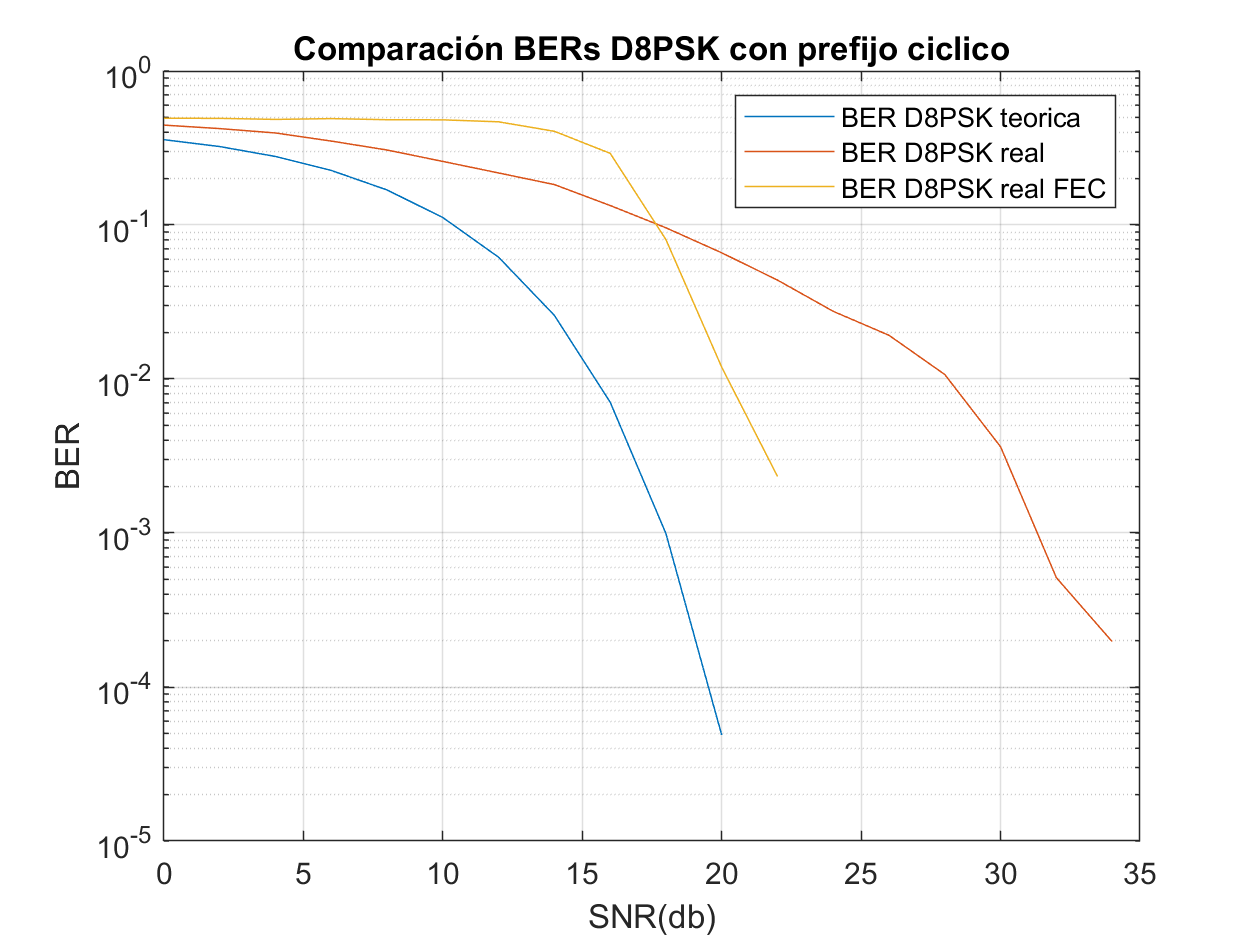


figure
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK_FEC)
title('Comparación BERs D8PSK con prefijo ciclico')
xlabel('SNR(db)')
ylabel('BER')
legend('BER D8PSK teorica', 'BER D8PSK real', 'BER D8PSK real FEC')
grid on

cada bit de output se influencia por los de alrededor. polinomios. Memoria y arrastra el error.